# Trabajo Práctico 1: Transformada Z - Ejercicio 3 - 4 y 5

## Ejercicio 3:

- Considere las transformadas $$X_1(z) = 1 + z^{-1} + 3z^{-2}$ y $X_2(z) = 1 + 3z^{-2}$$.

- ¿Cuál es su X(z) y su ROC?

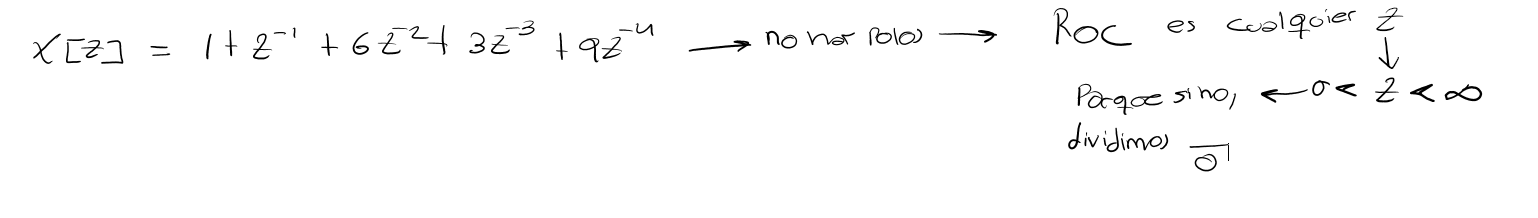

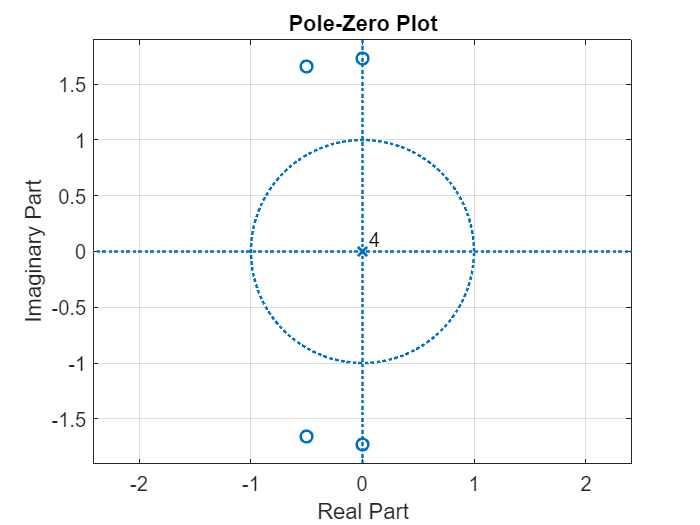


clc
clear
close all

b = [1 1 6 3 9];   % numerador
a = 1;             % denominador

figure
zplane(b,a)
grid on

## Ejercicio 4:

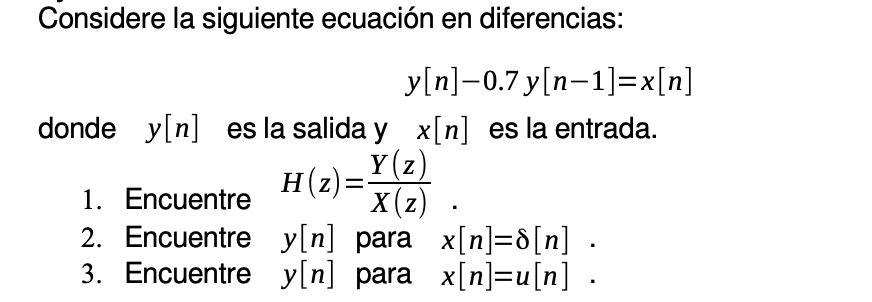

Utilice la función residuez para encontrar los polos de la función. Use la función filter para representar la respuesta del sistema en el dominio del tiempo.

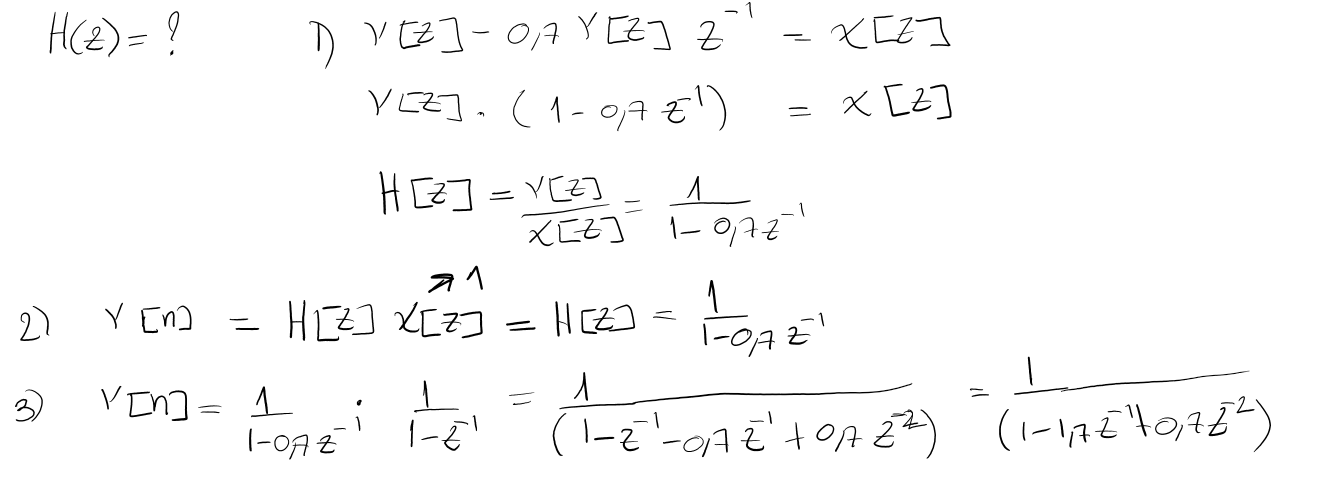

b1 = 1;
a1 = [1 -0.7];
[r1,p1,k1] = residuez(b1,a1)

r1 = 1

p1 = 0.7000


k1 =

     []



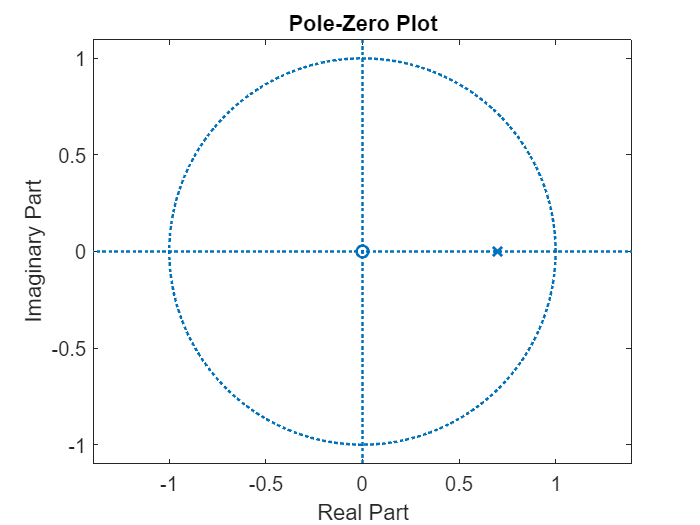

zplane(b1,a1)
hold on
hold off

b2 = 1;
a2 = [1 -1.7 0.7];
[r2,p2,k2] = residuez(b2,a2)

r2 =     3.3333
   -2.3333


p2 =     1.0000
    0.7000



k2 =

     []



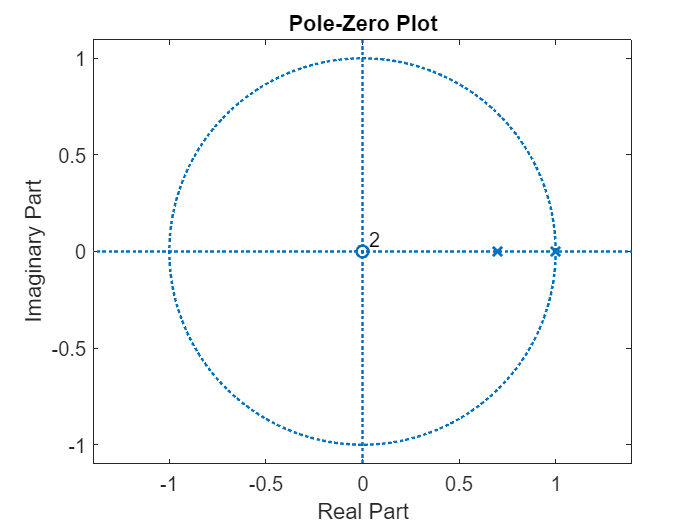

zplane(b2,a2)
hold on
hold off

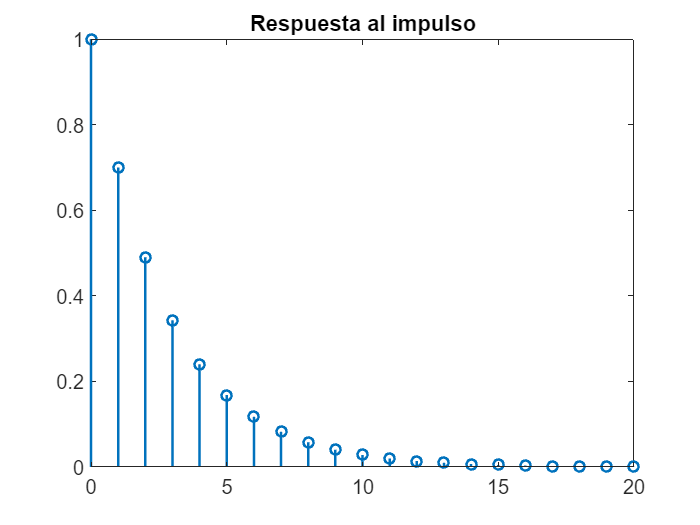


bf1 = 1;
af1 = [1 -0.7];
n = 0:20;
x = [1 zeros(1,20)];
y_delta = filter(bf1,af1,x);
x = ones(1,21);
y_step = filter(bf1,af1,x);


figure
stem(n,y_delta)
title('Respuesta al impulso')

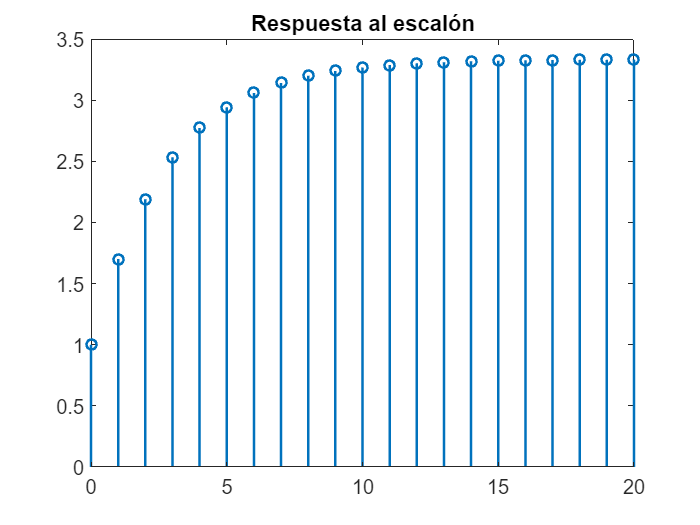

figure
stem(n,y_step)
title('Respuesta al escalón')

## Ejercicio 5:

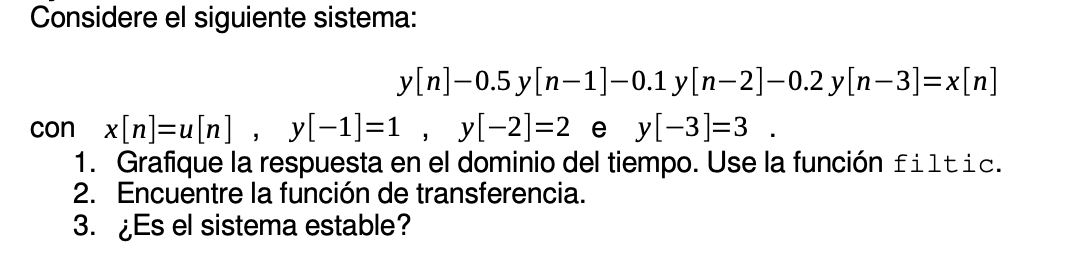

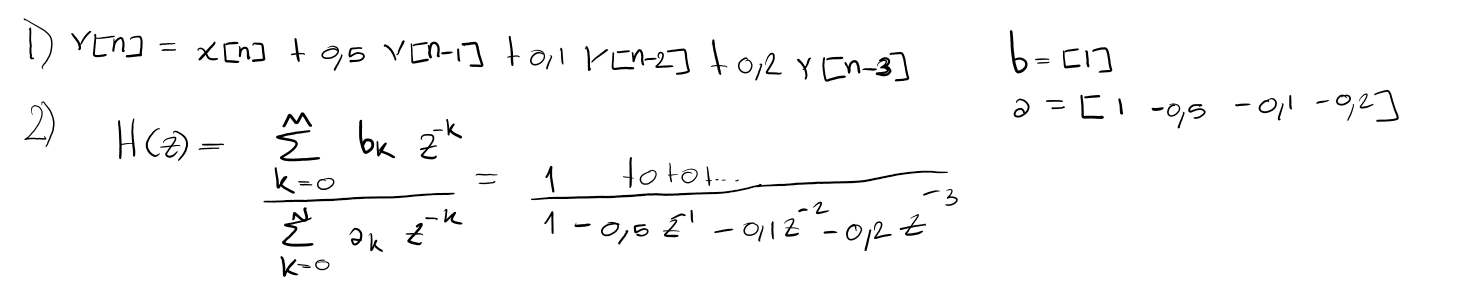

a = [1 -0.5 -0.1 -0.2]

a =     1.0000   -0.5000   -0.1000   -0.2000


b = [1]

b = 1


Y = [1 2 3];
xic = filtic(b,a,Y)

xic =     1.3000    0.5000    0.2000


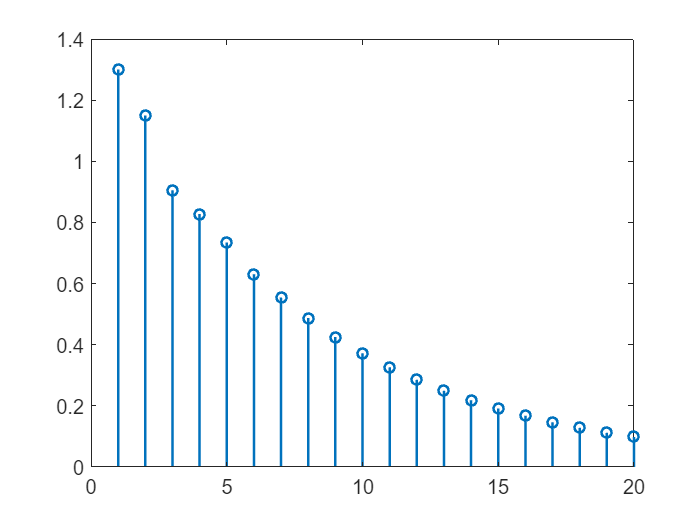

yzi = filter(b,a,zeros(1,20),xic);
stem(yzi)

p = roots(a)

p =    0.8753 + 0.0000i
  -0.1876 + 0.4396i
  -0.1876 - 0.4396i


% Ver módulos
abs(p)

ans =     0.8753
    0.4780
    0.4780


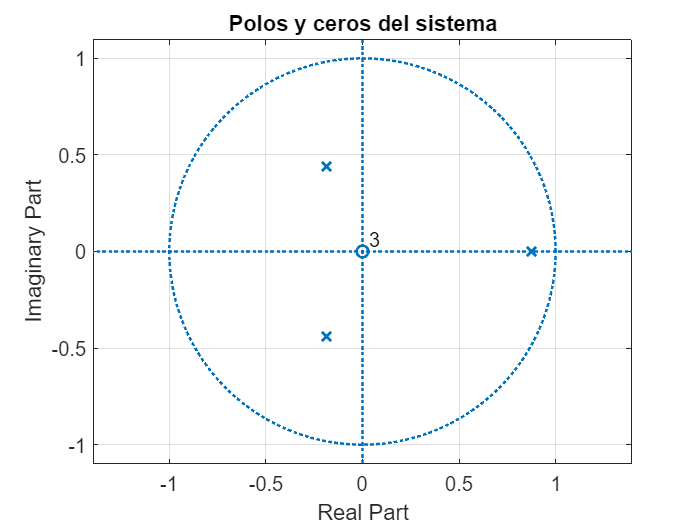


% Plano z
figure
zplane(b,a)
grid on
title('Polos y ceros del sistema')

%El sistema es estable

### Conclusiones

- En este ejercicio concluimos que 